
format long e; 

(4/3 - 1) * 3 - 1

ans =     -2.220446049250313e-16


5 * ((1 + exp(-50)) - 1) / ((1 + exp(-50)) - 1)

ans =    NaN


log(exp(750)) / 100

ans =    Inf



f1 = @(x) (tan(x) - x) ./ (x.^3);
l1 = 1/3; % Exact limit as x -> 0 (from Taylor series)

for p = 1:16
    x = 10^(-p);
    computed_val = f1(x);
    abs_error = abs(computed_val - l1)
    sig = -log10(abs_error / abs(l1))
    if sig < 1
        break;
    end
end

abs_error =      1.338752117210240e-03


sig =      2.396178574611669e+00


abs_error =      1.333387369062411e-05


sig =      4.397922408464452e+00


abs_error =      1.333982557194524e-07


sig =      6.397728594383236e+00


abs_error =      3.185574748432174e-09


sig =      8.019690945169842e+00


abs_error =      4.576003483913738e-07


sig =      5.862392398847657e+00


abs_error =      2.586858876607590e-05


sig =      4.110106008400804e+00


abs_error =      2.461088312122217e-03


sig =      2.131751547351923e+00


abs_error =      3.333333333333333e-01


sig =      0




f2 = @(x) (exp(x) + cos(x) - sin(x) - 2) ./ (x.^3);
l2 = 1/3; % Exact limit as x -> 0 (from Taylor series)
for p = 1:16
    x = 10^(-p);
    computed_val = f2(x);
    abs_error = abs(computed_val - l2)
    sig = -log10(abs_error / abs(l2))
    if sig < 1
        break;
    end
end

abs_error =      8.333373512100395e-03


sig =      1.602057897402991e+00


abs_error =      8.333334488762612e-04


sig =      2.602059931112379e+00


abs_error =      8.351635157549664e-05


sig =      3.601107231428165e+00


abs_error =      1.776632640636544e-04


sig =      3.273281108492356e+00


abs_error =      1.107558765167295e-01


sig =      4.785119668540234e-01



f3 = @(x) (exp(x) - 1) ./ x;
l3 = 1; % Exact limit as x -> 0 (from definition of derivative)

for p = 1:16
    x = 10^(-p);
    computed_val = f3(x);
    abs_error = abs(computed_val - l3)
    sig = -log10(abs_error / abs(l3))
    if sig < 1
        break;
    end
end

abs_error =      5.170918075647712e-02


sig =      1.286432342826650e+00


abs_error =      5.016708416794913e-03


sig =      2.299581140482518e+00


abs_error =      5.001667083845973e-04


sig =      3.300885218735133e+00


abs_error =      5.000166714097531e-05


sig =      4.301015515302865e+00


abs_error =      5.000006964905879e-06


sig =      5.301029390700364e+00


abs_error =      4.999621836532242e-07


sig =      6.301062843767653e+00


abs_error =      4.943368026033568e-08


sig =      7.305977055789310e+00


abs_error =      6.077470970922150e-09


sig =      8.216277106889963e+00


abs_error =      8.274037099909037e-08


sig =      7.082282536105524e+00


abs_error =      8.274037099909037e-08


sig =      7.082282536105524e+00


abs_error =      8.274037099909037e-08


sig =      7.082282536105524e+00


abs_error =      8.890058234101161e-05


sig =      4.051095394185471e+00


abs_error =      7.992778373591136e-04


sig =      3.097302229124561e+00


abs_error =      7.992778373591136e-04


sig =      3.097302229124561e+00


abs_error =      1.102230246251565e-01


sig =      9.577276756913117e-01


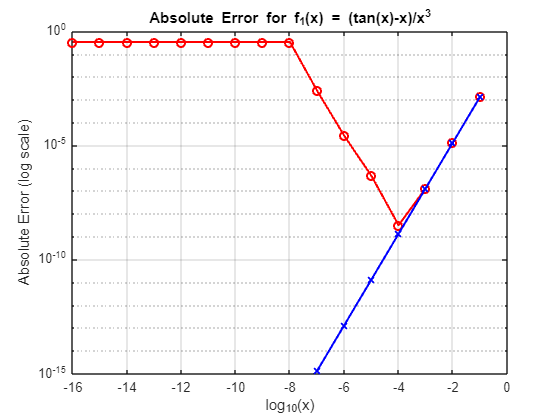



% tan(x) = x + x^3/3 + 2x^5/15 + ...
% (tan(x) - x) / x^3 = (x^3/3 + 2x^5/15 + ...) / x^3 = 1/3 + 2x^2/15 + ...
f1_new = @(x) 1/3 + (2*x.^2)/15;


% exp(x) = 1 + x + x^2/2 + x^3/6 + x^4/24 + ...
% cos(x) = 1 - x^2/2 + x^4/24 - ...
% sin(x) = x - x^3/6 + ...
% Numerator = (1+x+x^2/2+x^3/6) + (1-x^2/2) - (x-x^3/6) - 2 + O(x^4)
%           = (2 + x^3/3) - 2 + O(x^4) = x^3/3 + O(x^4)
% Expression = (x^3/3) / x^3 = 1/3 + O(x)
f2_new = @(x) 1/3 + x/12; % Using one more term (x^4/12) for better accuracy



% exp(x) = 1 + x + x^2/2! + ...
% (exp(x) - 1)/x = (x + x^2/2 + ...)/x = 1 + x/2 + ...
% MATLAB has a built-in function 'expm1(x)' which is x*(1 + x/2! + ...)
% So we can use expm1(x)/x for a stable computation.
f3_new = @(x) expm1(x)./x;



x_vals = 10.^-(1:16);
log_x_vals = log10(x_vals);

err1_original = abs(f1(x_vals) - l1);
err1_new = abs(f1_new(x_vals) - l1);

figure(1);
semilogy(log_x_vals, err1_original, 'r-o', 'LineWidth', 1.5);
hold on;
semilogy(log_x_vals, err1_new, 'b-x', 'LineWidth', 1.5);
hold off;
title('Absolute Error for f_1(x) = (tan(x)-x)/x^3');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');

grid on;

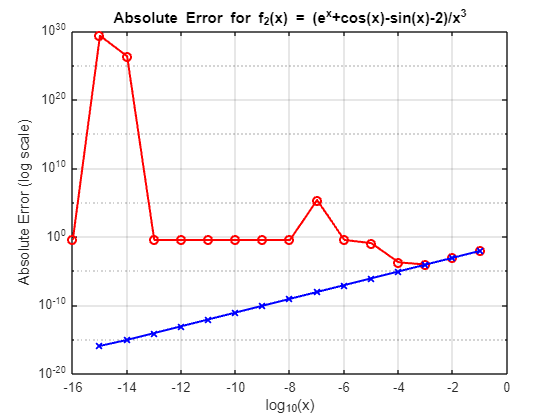


% Plot for Function (ii)
err2_original = abs(f2(x_vals) - l2);
err2_new = abs(f2_new(x_vals) - l2);

figure(2);
semilogy(log_x_vals, err2_original, 'r-o', 'LineWidth', 1.5);
hold on;
semilogy(log_x_vals, err2_new, 'b-x', 'LineWidth', 1.5);
hold off;
title('Absolute Error for f_2(x) = (e^x+cos(x)-sin(x)-2)/x^3');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');

grid on;

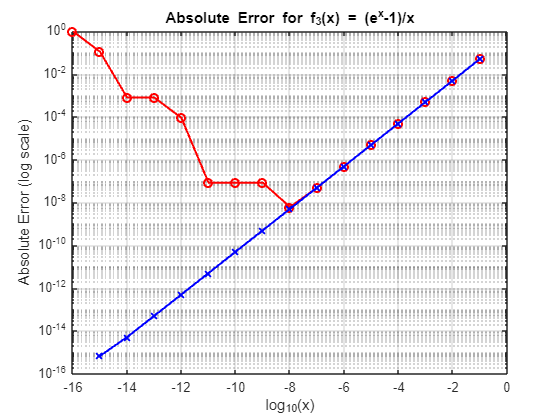


% Plot for Function (iii)
err3_original = abs(f3(x_vals) - l3);
err3_new = abs(f3_new(x_vals) - l3);

figure(3);
semilogy(log_x_vals, err3_original, 'r-o', 'LineWidth', 1.5);
hold on;
semilogy(log_x_vals, err3_new, 'b-x', 'LineWidth', 1.5);
hold off;
title('Absolute Error for f_3(x) = (e^x-1)/x');
xlabel('log_{10}(x)');
ylabel('Absolute Error (log scale)');

grid on;





% --- Part 3.b: Bisection Method for p(x) = (x-2)^9 ---

% Define the coefficients of p(x) = (x-2)^9.
% p(x) = x^9 - 18x^8 + 144x^7 - 672x^6 + 2016x^5 - 4032x^4 + 5376x^3 ...
%        - 4608x^2 + 2304x - 512
p_coeffs = [1, -18, 144, -672, 2016, -4032, 5376, -4608, 2304, -512];
tol = 1e-8;


% Test Case 1
x0_1 = 1.96; x1_1 = 2.04;
root1 = bisect_poly(p_coeffs, x0_1, x1_1, tol)

root1 =    NaN



% Test Case 2
x0_2 = 1.98; x1_2 = 2.02;
root2 = bisect_poly(p_coeffs, x0_2, x1_2, tol)

root2 =      2



% Test Case 3
x0_3 = 1.99; x1_3 = 2.01;
root3 = bisect_poly(p_coeffs, x0_3, x1_3, tol)

root3 =      2


The bisection method struggles to find the root accurately. The results are often not close to 2 and can be erratic. This happens because the expanded polynomial evaluation using Horner's method is numerically unstable near the root x=2. Small floating-point errors cause the evaluated polynomial to oscillate wildly around zero, violating the bisection method's core assumption that p(x0)*p(x1) < 0 consistently holds as the interval shrinks.

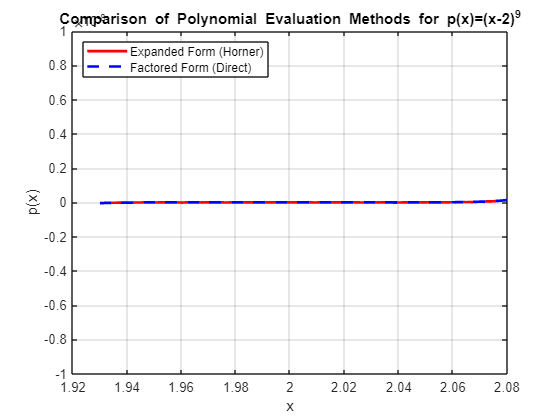


x_eval = linspace(1.93, 2.08, 151);

y_horner = Horner(p_coeffs, x_eval);

y_direct = (x_eval - 2).^9;


figure(4);
plot(x_eval, y_horner, 'r-', 'LineWidth', 2);
hold on;
plot(x_eval, y_direct, 'b--', 'LineWidth', 2);
grid on;
hold off;
title('Comparison of Polynomial Evaluation Methods for p(x)=(x-2)^9');
xlabel('x');
ylabel('p(x)');
legend('Expanded Form (Horner)', 'Factored Form (Direct)', 'Location', 'NorthWest');
ylim([-1e-8, 1e-8]); % Zoom in to see the oscillations

 The bisection method relies on the function having opposite signs at the interval endpoints. Because the Horner evaluation oscillates, it creates many misleading "roots" and sign changes in the tiny interval around x=2. The bisection algorithm might converge to one of these incorrect sign-change locations, or fail to find a valid bracket, leading to the highly inaccurate results observed.

function y = Horner(p, x)


    n = length(p);
    y = p(1) * ones(size(x)); % Initialize y with the first coefficient

    for i = 2:n
        y = y .* x + p(i);
    end
end

function x_root = bisect_poly(p, x0, x1, tol)
    p0 = Horner(p, x0);
    p1 = Horner(p, x1);

    if p0 * p1 >= 0
        x_root = NaN; % Return NaN if condition isn't met
        return;
    end

    while (x1 - x0) / 2 > tol
        c = (x0 + x1) / 2;
        pc = Horner(p, c);
        if pc == 0
            x_root = c;
            return;
        end
        if p0 * pc < 0
            x1 = c;
        else
            x0 = c;
            p0 = pc; % Update p0 to the value at the new x0
        end
    end
    x_root = (x0 + x1) / 2;
end

